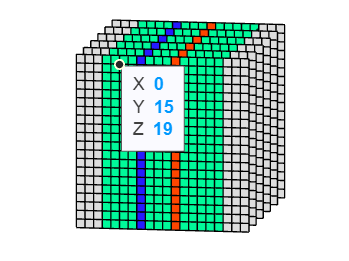

clear; clc; close all
% 设置图像的属性
figure;
hold on;

% 网格大小
rows = 6;
cols = 20;
depth = 20;

% 创建一个3D网格的坐标
[X, Y, Z] = meshgrid(1:cols, 1:rows, 1:depth);

% 设置不同时间点的颜色
% colors = [linspace(1, 0, depth); linspace(1, 0, depth); linspace(0, 1, depth)]';

% 浅灰
rgb_color = [221/255, 221/255, 221/255];  % RGB(220, 220, 220) 转换为归一化的值
colors = repmat(rgb_color, depth, 1);  % 创建一个与 depth 相关的颜色矩阵

% 绿色
green_color = [0 0.9804 0.6039];
visble=4:17;
colors(visble,:)=repmat(green_color, length(visble), 1);

% 红色
red_color = [1 0.2706 0];
visble=9;
colors(visble,:)=repmat(red_color, length(visble), 1);


% 蓝色
blue_color =[0.1451 0.102 1];
visble=13;
colors(visble,:)=repmat(blue_color, length(visble), 1);

% % 黄色
% yellow_color = [1 1 0];
% visble=11;
% colors(visble,:)=repmat(yellow_color, length(visble), 1);

% 绘制每个时间步的矩形
for t = 1:depth
    % 使用不同的颜色来表示不同的时间
    
    
    % 画出矩形，逐步增加时间步
    for i = 1:rows
        for j = 1:cols
            % 为每个网格单元画一个小立方体
            % 位置调整
            color = colors(j,:);
            x_offset = 5*(i-1);
            y_offset = j-1;
            z_offset = t-1;

            % 绘制立方体
            fill3([x_offset, x_offset, x_offset, x_offset], ...
                  [y_offset, y_offset, y_offset+1, y_offset+1], ...
                  [z_offset, z_offset+1, z_offset+1, z_offset], color, 'EdgeColor', 'black');
            
        end
    end
end

% 添加时间标签
for t = 1:depth
    text(cols+0.5, rows/2, t-1, sprintf('t_{%d}', t-1), 'Color', 'k', 'FontSize', 12);
end

% 设置坐标轴
axis off;
axis equal;
set(gca, 'XTick', [], 'YTick', [], 'ZTick', []);
xlabel('Fast time x');
ylabel('Slow time y');
zlabel('Angle z');
view(3);
hold off;

view([-80.6 9.1])

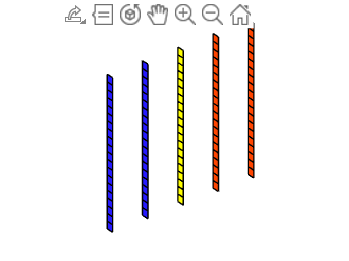

clear; clc; close all
% 设置图像的属性
figure;
hold on;

% 网格大小
rows = 5;
cols = 1;
depth = 20;

% 创建一个3D网格的坐标
[X, Y, Z] = meshgrid(1:cols, 1:rows, 1:depth);

% 设置不同时间点的颜色
% colors = [linspace(1, 0, depth); linspace(1, 0, depth); linspace(0, 1, depth)]';

% 浅灰
rgb_color = [221/255, 221/255, 221/255];  % RGB(220, 220, 220) 转换为归一化的值
colors = repmat(rgb_color, rows, 1);  % 创建一个与 rows 相关的颜色矩阵

% 绿色
% green_color = [0 0.9804 0.6039];
% visble=4:17;
% colors(visble,:)=repmat(green_color, length(visble), 1);




% 红色
red_color = [1 0.2706 0];
period = 5;
start_indices = 1:period:rows; % [1, 6, 11, 16]
selected_channels = [start_indices+3; start_indices + 4];
visble = selected_channels(:)';
colors(visble,:)=repmat(red_color, length(visble), 1);


% 蓝色
blue_color =[0.1451 0.102 1];
period = 5;
start_indices = 1:period:rows; % [1, 6, 11, 16]
selected_channels = [start_indices; start_indices + 1];
visble = selected_channels(:)';
colors(visble,:)=repmat(blue_color, length(visble), 1);

% 黄色
yellow_color = [1 1 0];
period = 5;
start_indices = 1:period:rows; % [1, 6, 11, 16]
selected_channels = start_indices+2;
visble = selected_channels(:)';
colors(visble,:)=repmat(yellow_color, length(visble), 1);

% 绘制每个时间步的矩形
for t = 1:depth
    % 使用不同的颜色来表示不同的时间
    
    
    % 画出矩形，逐步增加时间步
    for i = 1:rows
        for j = 1:cols
            % 为每个网格单元画一个小立方体
            % 位置调整
            color = colors(i,:);
            x_offset = 5*(i-1);
            y_offset = j-1;
            z_offset = t-1;

            % 绘制立方体
            fill3([x_offset, x_offset, x_offset, x_offset], ...
                  [y_offset, y_offset, y_offset+1, y_offset+1], ...
                  [z_offset, z_offset+1, z_offset+1, z_offset], color, 'EdgeColor', 'black');
            
        end
    end
end

% % 添加时间标签
% for t = 1:depth
%     text(cols+0.5, rows/2, t-1, sprintf('t_{%d}', t-1), 'Color', 'k', 'FontSize', 12);
% end

% 设置坐标轴
axis off;
axis equal;
set(gca, 'XTick', [], 'YTick', [], 'ZTick', []);
xlabel('Fast time x');
ylabel('Slow time y');
zlabel('Angle z');
view(3);
hold off;
axis tight 

% view([-80.6 9.1])

     1     2     6     7    11    12    16    17

